# Simscape multibody model of Regbot in balance

initial setup with motor velocity controller this is intended as simulation base for balance control.

close all
clear

## Simulink model name

model='regbot_1mg';

## parameters for REGBOT

motor

RA = 3.3/2;    % ohm (2 motors)
JA = 1.3e-6*2; % motor inertia
LA = 6.6e-3/2; % rotor inductor (2 motors)
BA = 3e-6*2;   % rotor friction
Kemf = 0.0105; % motor constant
Km = Kemf;
% køretøj
NG = 9.69; % gear
WR = 0.03; % wheel radius
Bw = 0.155; % wheel distance
% 
% model parts used in Simulink
mmotor = 0.193;   % total mass of motor and gear [kg]
mframe = 0.32;    % total mass of frame and base print [kg]
mtopextra = 0.97 - mframe - mmotor; % extra mass on top (charger and battery) [kg]
mpdist =  0.10;   % distance to lit [m]
% disturbance position (Z)
pushDist = 0.1; % relative to motor axle [m]

## wheel velocity controller (no balance) PI-regulator

sample (usable) controller values

Kpwv = 15;     % Kp
tiwv = 0.05;   % Tau_i
Kffwv = 0;     % feed forward constant
startAngle = 10;  % tilt in degrees at time zero
twvlp = 0.005;    % velocity noise low pass filter time constant (recommended)

## Motor voltage to wheel velocity

### Estimate transfer function for base system using LINEARIZE

Motor volatge to wheel velocity (wv)

load_system(model);
open_system(model);
% define points in model
ios(1) = linio(strcat(model,'/Limit9v'),1,'openinput');
ios(2) = linio(strcat(model, '/wheel_vel_filter'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gwv = minreal(tf(num, den))

Gwv =
 
                  7.023e05 s^3 + 7.023e08 s^2 - 5.083e07 s - 5.083e10
  -----------------------------------------------------------------------------------
  s^6 + 2418 s^5 + 1.317e06 s^4 + 1.872e08 s^3 + 2.371e09 s^2 - 3.032e10 s - 1.881e11
 
Continuous-time transfer function.



### Bodeplot

h = figure(100)

h =   Figure (100) with properties:

      Number: 100
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


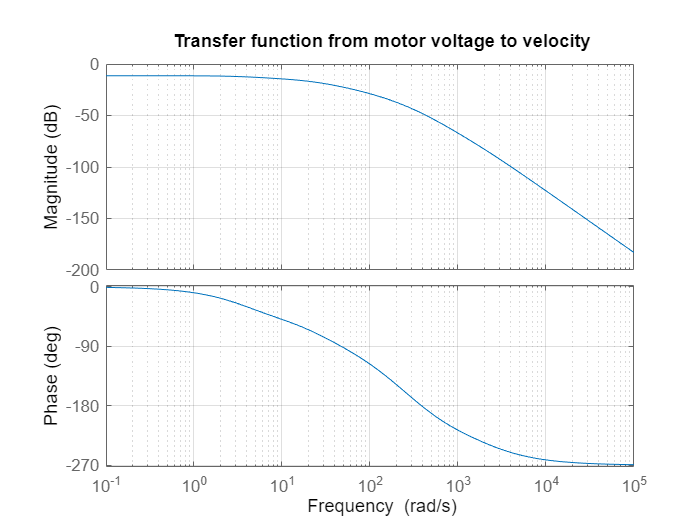

bode(Gwv)
grid on
title('Transfer function from motor voltage to velocity')
saveas(h, 'motor to velocity.png');

## Voltage to tilt angle

### Estimate transfer function for base system using LINEARIZE

Motor volatge to wheel velocity (wv)

load_system(model);
open_system(model);
% define points in model
iosang(1) = linio(strcat(model,'/Step'),1,'openinput');
iosang(2) = linio(strcat(model, '/robot with balance'),1,'openoutput');
% attach to model
setlinio(model,iosang);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,iosang,op);
% get transfer function
[numang,denang] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gva = minreal(tf(numang, denang))

Gva =
 
                  -5.893e05 s^4 - 7.71e08 s^3 - 1.435e11 s^2 - 2.566e12 s - 7.683e09
  --------------------------------------------------------------------------------------------------
  s^7 + 2418 s^6 + 1.317e06 s^5 + 1.977e08 s^4 + 1.312e10 s^3 + 1.796e11 s^2 - 9.658e11 s - 1.525e13
 
Continuous-time transfer function.



### Bodeplot

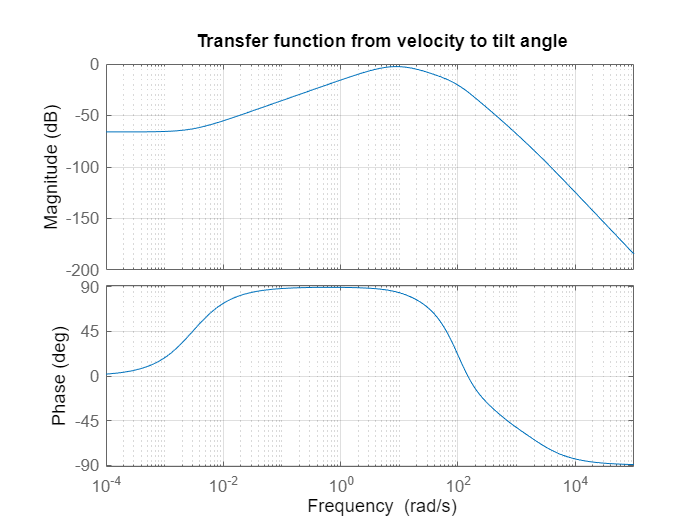

figure(101);
bode(Gva)
grid on
title('Transfer function from velocity to tilt angle')  

### Stabilize the system

Get the bode of the transfer function multiplied by -1

Find the peak in the bode plot

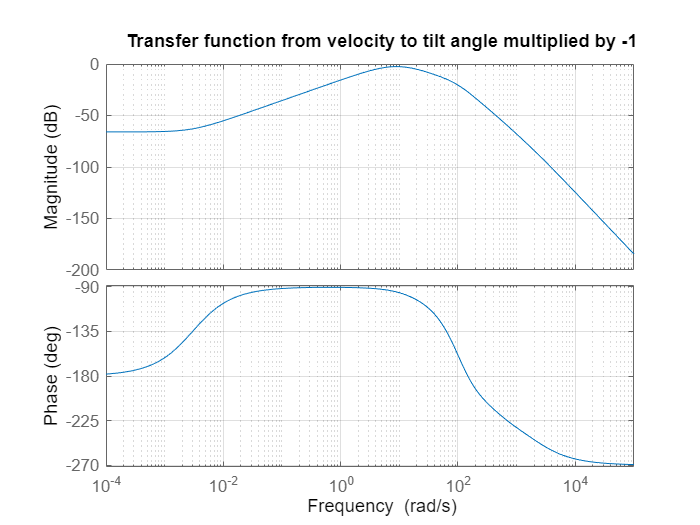

figure();
bode(-1*Gva)
grid on
title('Transfer function from velocity to tilt angle multiplied by -1')

#### Design the PI controller

Implement a PI controller right where there is a peak in the bode plot

s = tf('s'); 
%Select the w_i in rad/s -> The PI will be placed at the peak at 10 rad/s
w_i = 10

w_i = 10

tau_i = 1/w_i;

% PI controller time constant and transfer function
C_PI = (1 + 1/(tau_i*s));

% Open-loop transfer function
G_ol = minreal(C_PI*-Gva);

%We define a w_c -> We want a good bandwidth
w_c = 2000;                 %How big should it be??

% P-controller gain
K_P = 1/abs(freqresp(G_ol,w_c));

C_PI

C_PI =
 
  0.1 s + 1
  ---------
    0.1 s
 
Continuous-time transfer function.



K_P

K_P = 1.6156e+04

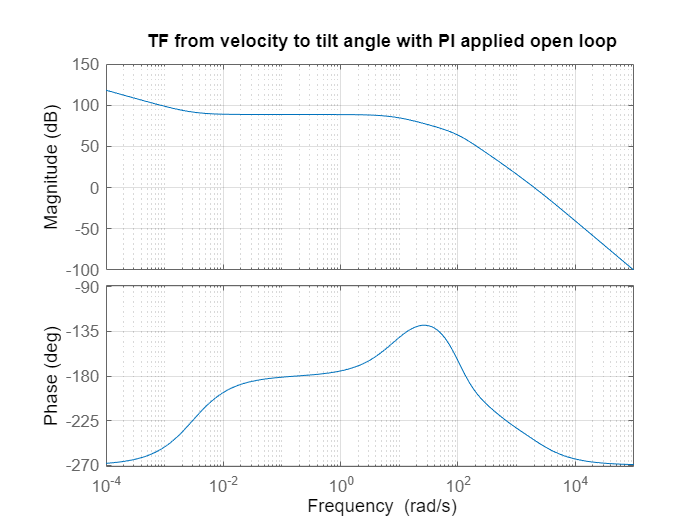



figure();
bode(-K_P*C_PI*Gva)
grid on
title('TF from velocity to tilt angle with PI applied open loop')

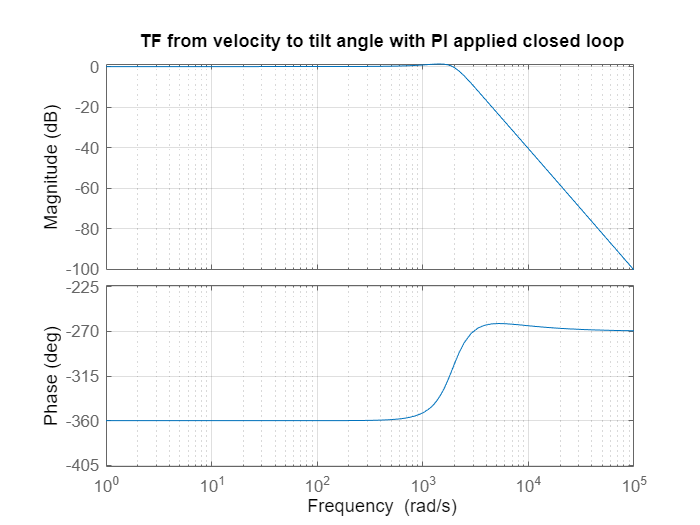



figure();
bode((-K_P*C_PI*Gva)/(1+(-K_P*C_PI*Gva)))
%Is the tf correctly defined?-----------------------------negative sign on
%the denominator??????

%Maybe we need a lead part to compensate the phase margin (cause its not
%-180 but -360 so idk if that's correct
%I suppose it must be stable and this thing doesn't look stable 

grid on
title('TF from velocity to tilt angle with PI applied closed loop')